# German Stocks - Importing I

## 1.

Open `DAX.xls` in Excel.  This file contains price series information from the German stock index DAX as well as its 30 constituent stocks.  Included are their names as column headers as well as date information in the first column.

winopen('DAX.xls')

## 2.

Import the data into a table. Use the stock/index names as variable names.

dax = readtable('DAX.xls')

dax = 901×32 table
       Date        DAX      Adidas    Allianz    BASF     Bayer    Beiersdorf     BMW     Commerzbank    Daimler    DeutscheBank    DeutscheBahn    Lufthansa    DeutschePost    DeutscheTelekom     EON     FreseniusMedical    Fresenius    Heidelberger    Henkel    Infineon    Salzgitter    Linde     MAN      MRK     Metro    MunichRe     RWE      SAP     Siemens    ThyssenKrupp     VW  
    __________    _____

## 3.

Remove all corrupted observations (one or more values missing within one row).

dax = rmmissing(dax)

dax = 891×32 table
       Date        DAX      Adidas    Allianz    BASF     Bayer    Beiersdorf     BMW     Commerzbank    Daimler    DeutscheBank    DeutscheBahn    Lufthansa    DeutschePost    DeutscheTelekom     EON     FreseniusMedical    Fresenius    Heidelberger    Henkel    Infineon    Salzgitter    Linde     MAN      MRK     Metro    MunichRe     RWE      SAP     Siemens    ThyssenKrupp     VW  
    __________    _____

## 4.

Create a matrix of prices from the variables `BMW`, `Daimler`, and `VW`.

prices = dax{:,{'BMW','Daimler','VW'}}

prices =    39.9000   41.2800   73.4300
   41.2600   43.2400   75.9400
   40.3600   42.0100   75.0700
   41.3600   43.4200   77.2300
   41.4900   43.9500   76.8100
   41.5100   44.4700   76.6500
   41.8000   44.5000   77.7300
   40.7100   43.1200   75.7500
   39.7000   42.3100   75.2000
   39.0300   41.1400   72.4400


## 5.

Visually compare the matrix of prices by plotting them on the same axes against date.

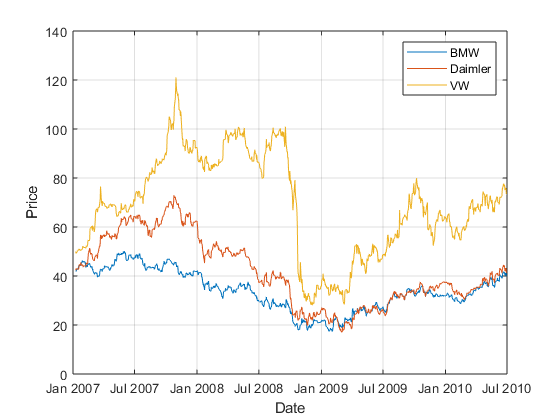

plot(dax.Date,prices)
grid('on')
legend('BMW','Daimler','VW')
xlabel('Date')
ylabel('Price')